# Design Custom YOLOv4 Object Detector(客製化YOLOv4模型)

% Bulit on 2022.6.13 by Fred Liu

#### Docnumentation：yolov4ObjectDetector

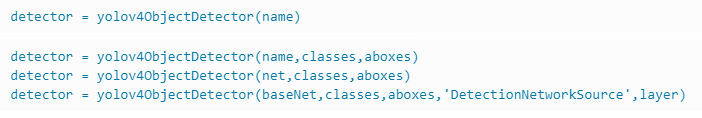

% Bulit on 2022.6.13 by Fred Liu

#### 基於最後一項，自定義客製化YOLOv4的方式

basenet = resnet50;
analyzeNetwork(basenet)
basenet.Layers(1)

自定義YOLOv4架構，必須做到以下對於基礎網路的更動

1.在第一層的ImageInputLayer中將初始化設定參數設定成none('Normalization','none')

2.移除全連接層

imageSize = basenet.Layers(1).InputSize;
layerName = basenet.Layers(1).Name;
newinputLayer = imageInputLayer(imageSize,'Normalization','none','Name',layerName);

建成lgraph

lgraph = layerGraph(basenet);

移除全連接層

lgraph = removeLayers(lgraph,'ClassificationLayer_fc1000');

把舊的影像輸入層替換掉

lgraph = replaceLayer(lgraph,layerName,newinputLayer);

轉換成dlnetwork框架

dlnet = dlnetwork(lgraph);

設定特徵提取層

featureExtractionLayers = ["activation_22_relu","activation_40_relu"];

類別與錨定框

classes = {'car','person'};
anchorBoxes = {[122,177;223,84;80,94];...
               [111,38;33,47;37,18]};

組成detector

detector = yolov4ObjectDetector(dlnet,classes,anchorBoxes,DetectionNetworkSource=featureExtractionLayers);